## Dane wejściowe

clear all
load("data\mass_data.mat","Iyy","Mass")
load("data\enviroment_data.mat","dynamic_pressure","v_sound")
load("data\wing_geometry.mat","S","MAC")
load("data\flight_cases_data.mat", "mach")
load("data\longitudinal_data.mat")
load("data\longitudinal_dimnsional_derivatives.mat")

## Wyznaczanie macierzy:

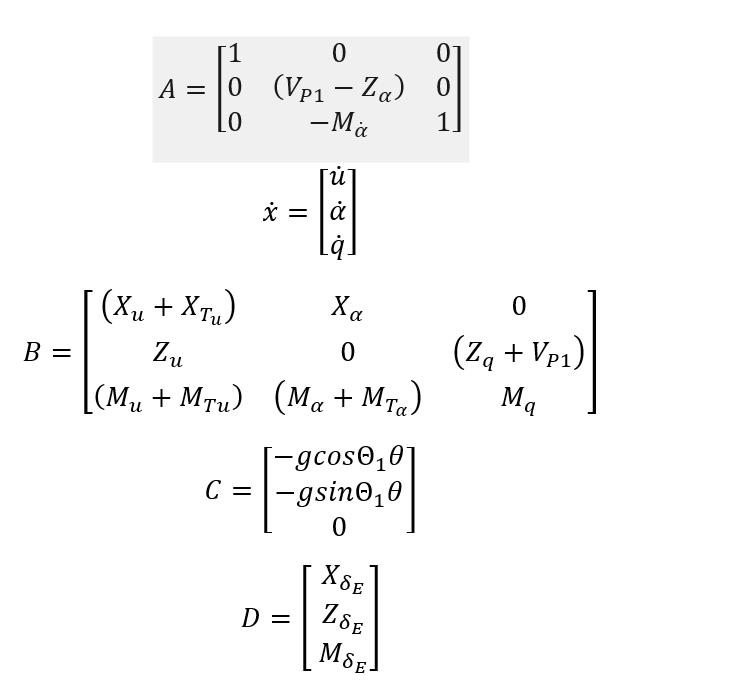

for i=1:1
    for o=2:2
        syms t u(t) alfa(t) q(t) delta(t)
        A= [1 0 0 ; 0 (Vp1(i,o)-Zalpha(i,o)) 0 ; 0 -Malphadot(i,o) 1];
        B= [(Xu(i,o)+Xtu(i,o)) Xalpha(i,o) 0 ; Zu(i,o) 0 (Zq(i,o)+Vp1(i,o)) ; (Mu(i,o)+Mtu(i,o)) (Mtalpha(i,o)+Mtalpha(i,o)) Mq(i,o)];
        C= [-gravity_acceleration(1)  0  0];
        D= [ XdeltaE(i,o)  ZdeltaE(i,o)  MdeltaE(i,o)];
        eqn1 = diff(u(t)) == (B(1,1)*u(t) + B(1,2)*alfa(t) + B(1,3)*q(t) + C(1) + D(1)*angleE(t)) / A(1,1);
        eqn2 = diff(alfa(t)) == (B(2,1)*u(t) + B(2,2)*alfa(t) + B(2,3)*q(t) + C(2) + D(2)*angleE(t)) / A(2,2);
        eqn3 = diff(q(t)) == (B(3,1)*u(t) + B(3,2)*alfa(t) + B(3,3)*q(t) + C(3) + D(3)*angleE(t)) / A(3,3);
        eqns = [eqn1, eqn2, eqn3];
        u0= 0;
        q0=0;
        alfa0=0;
        conds = [u(0)==u0, alfa(0)==alfa0, q(0)==q0]; 
        [x1Sol(t), x2Sol(t), x3Sol(t)] = dsolve(eqns, conds);
    end
    t=linspace(0,100,1000);
    u1=double(x1Sol(t))
    alfa1=double(x2Sol(t))
    theta1=double(x3Sol(t))
    deltaE1= angleE(t)
    save("data\values","u1","alfa1","theta1")
end

u1 =   -0.0000 + 0.0000i   0.0004 - 0.0000i   0.0017 + 0.0000i   0.0037 + 0.0000i   0.0064 - 0.0000i   0.0099 + 0.0000i   0.0141 + 0.0000i   0.0189 - 0.0000i   0.0244 - 0.0000i   0.0305 + 0.0000i   0.0372 + 0.0000i   0.0444 + 0.0000i   0.0522 + 0.0000i   0.0605 - 0.0000i   0.0693 + 0.0000i   0.0786 - 0.0000i   0.0884 - 0.0000i   0.0986 - 0.0000i   0.1092 + 0.0000i   0.1203 - 0.0000i   0.1317 - 0.0000i   0.1436 + 0.0000i   0.1558 + 0.0000i   0.1684 - 0.0000i   0.1813 + 0.0000i   0.1945 + 0.0000i   0.2081 + 0.0000i   0.2220 - 0.0000i   0.2362 - 0.0000i   0.2506 - 0.0000i  -2.0737 - 1.7902i  -2.0201 - 1.8127i  -1.9722 - 1.8344i  -1.9294 - 1.8553i  -1.8915 - 1.8753i  -1.8581 - 1.8945i  -1.8287 - 1.9130i  -1.8032 - 1.9306i  -1.7812 - 1.9475i  -1.7625 - 1.9635i  -1.7467 - 1.9788i  -1.7338 - 1.9933i  -1.7233 - 2.0071i  -1.7153 - 2.0200i  -1.7094 - 2.0323i  -1.7055 - 2.0438i  -1.7034 - 2.0545i  -1.7030 - 2.0646i  -1.7041 - 2.0739i  -1.7066 - 2.0825i


alfa1 =    0.0000 + 0.0000i  -0.0000 - 0.0000i  -0.0001 + 0.0000i  -0.0002 + 0.0000i  -0.0003 + 0.0000i  -0.0004 + 0.0000i  -0.0006 + 0.0000i  -0.0008 - 0.0000i  -0.0010 + 0.0000i  -0.0012 + 0.0000i  -0.0015 - 0.0000i  -0.0017 + 0.0000i  -0.0020 + 0.0000i  -0.0023 + 0.0000i  -0.0026 + 0.0000i  -0.0029 + 0.0000i  -0.0032 + 0.0000i  -0.0035 + 0.0000i  -0.0038 - 0.0000i  -0.0041 + 0.0000i  -0.0045 + 0.0000i  -0.0048 + 0.0000i  -0.0051 - 0.0000i  -0.0055 + 0.0000i  -0.0058 + 0.0000i  -0.0061 - 0.0000i  -0.0065 + 0.0000i  -0.0068 + 0.0000i  -0.0071 + 0.0000i  -0.0075 + 0.0000i  -0.0441 + 0.0429i  -0.0533 + 0.0421i  -0.0619 + 0.0412i  -0.0699 + 0.0403i  -0.0773 + 0.0395i  -0.0842 + 0.0386i  -0.0906 + 0.0378i  -0.0966 + 0.0369i  -0.1022 + 0.0361i  -0.1074 + 0.0352i  -0.1122 + 0.0344i  -0.1167 + 0.0336i  -0.1209 + 0.0327i  -0.1248 + 0.0319i  -0.1285 + 0.0311i  -0.1319 + 0.0302i  -0.1350 + 0.0294i  -0.1380 + 0.0286i  -0.1408 + 0.0278i  -0.1433 + 0.0269i


theta1 = 1.0e+02 *

  -0.0000 + 0.0000i  -0.0320 - 0.0000i  -0.0637 + 0.0000i  -0.0949 + 0.0000i  -0.1258 + 0.0000i  -0.1563 + 0.0000i  -0.1864 + 0.0000i  -0.2160 - 0.0000i  -0.2453 + 0.0000i  -0.2741 + 0.0000i  -0.3024 - 0.0000i  -0.3304 + 0.0000i  -0.3579 + 0.0000i  -0.3849 + 0.0000i  -0.4115 + 0.0000i  -0.4376 + 0.0000i  -0.4633 + 0.0000i  -0.4885 + 0.0000i  -0.5133 - 0.0000i  -0.5376 + 0.0000i  -0.5614 + 0.0000i  -0.5847 + 0.0000i  -0.6076 - 0.0000i  -0.6300 + 0.0000i  -0.6519 + 0.0000i  -0.6733 - 0.0000i  -0.6943 + 0.0000i  -0.7148 - 0.0000i  -0.7348 - 0.0000i  -0.7543 + 0.0000i  -3.4128 + 2.0340i  -3.4432 + 1.9794i  -3.4724 + 1.9251i  -3.5004 + 1.8709i  -3.5274 + 1.8170i  -3.5535 + 1.7633i  -3.5787 + 1.7099i  -3.6032 + 1.6568i  -3.6270 + 1.6040i  -3.6501 + 1.5514i  -3.6727 + 1.4992i  -3.6948 + 1.4473i  -3.7164 + 1.3957i  -3.7376 + 1.3444i  -3.7585 + 1.2935i  -3.7790 + 1.2429i  -3.7993 + 1.1927i  -3.8193 + 1.1429i  -3.8391 + 1.0935i  -3.8587 + 1.0444i


## Wykresownik

tiledlayout(2,2);
nexttile
plot(t,rad2deg(deltaE1))
xlabel('time[s]')
ylabel('\delta_E [\circ]')
grid minor
nexttile
plot(t,u1)

xlabel('time[s]')
ylabel('u [ft/s]')
grid minor
nexttile
plot(t,rad2deg(alfa1))

xlabel('time[s]')
ylabel('\alpha [\circ]')
grid minor
nexttile
plot(t,rad2deg(theta1))

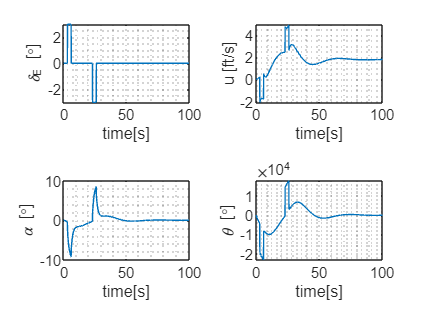

xlabel('time[s]')
ylabel('\theta [\circ]')
grid minor

function deltaE= angleE(t)
    valuer=deg2rad(3);
    deltaE=valuer*(heaviside(t-3)-heaviside(t-6)-heaviside(t-23)+heaviside(t-26));
end